%%punto de operacion Theta=0
x0 = [0;0;0;0;0];
u0 = [0];
y0 = [0;0;0;0;0];

xf = [3,5];
uf = [];
yf = [];

[x_op,u_op,y_op] = trim("trim_simulation",x0,u0,y0,xf,uf,yf)

x_op =      0
     0
     0
     0
     0


u_op = 0

y_op =      0
     0
     0
     0
     0



[A,B,C,D] = linmod("trim_simulation",x_op,u_op);

sys=ss(A,B,C,D);

polos_punto_0=eig(A)

polos_punto_0 =          0
   -0.2158
         0
    9.8652
   -9.8652


%%punto de operacion Theta=pi
x1 = [0;pi;0;0;0];
u1 = [0];
y1 = [0;0;0;0;0];

xf1 = [3,5];
uf1 = [];
yf1 = [];

[x_pi,u_pi,y_pi] = trim("trim_simulation",x1,u1,y1,xf1,uf1,yf1)

x_pi =          0
    3.1416
         0
         0
         0


u_pi = 0

y_pi =          0
    3.1416
         0
         0
         0



[A1,B1,C1,D1] = linmod("trim_simulation",x_pi,u_pi);

sys1=ss(A1,B1,C1,D1);

polos_punto_pi=eig(A1)

polos_punto_pi =    0.0000 + 0.0000i
  -0.2158 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 9.8652i
   0.0000 - 9.8652i


## parametros reubicacion de polos

ts=1;     %1 segundo
SP=1/1000;     %sin sobrepaso
Ba=2/100; %2% de banda de asentamiento

Tau=ts/5;
chi=abs(log(SP))/sqrt(pi^2+log(SP)^2); %factor de asentamiento
Wn=log(1/Ba*(sqrt(1-chi^2)))/(ts*chi);%frecuencia natural

den=[1, 2*Wn*chi, Wn^2];
r=roots(den)%polos FT segundo orden

r =   -3.0301 + 1.3781i
  -3.0301 - 1.3781i


%%polos controlador
polos_controlador=[r(1), r(2), 5*real(r(1)), 6*real(r(2)), 0];% polos dominantes complejos conjugado

%%Ubicacion de polos
Kc=place(A1,B1,polos_controlador);
At=A1-B1*Kc;
Bt=zeros(size(B1));
Ct=C1-D1*Kc;
Dt=zeros(size(D1));

%%polos rebicados
eig(At)

ans =    0.0000 + 0.0000i
 -18.1806 + 0.0000i
 -15.1505 + 0.0000i
  -3.0301 + 1.3781i
  -3.0301 - 1.3781i


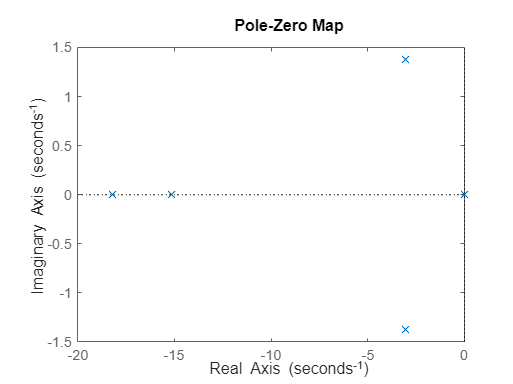

H1=ss(At,Bt,Ct,Dt);
pzmap(H1)


%la pregunta es como agregar el K al tema que me interesa